# II. Discrete Wavelet Transform

## 2.2. Applying DWT with the Wavelet Toolbox in MATLAB 

N = 1024; % length of the total signal
fs = 512; % sampling frequency
n = 0:1023;

% Constructing necessary input signals

x1_n_1 = 2*sin(20*pi*n/fs) + sin(80*pi*n/fs);
x1_n_2 = 0.5*sin(40*pi*n/fs) + sin(60*pi*n/fs);

x1_n = [x1_n_1(n>=0 & n<512) x1_n_2(n>=512 & n<1024)];

x2_n_1 = ones(1,1024);
x2_n = [1.*x2_n_1(n >= 0 & n < 64), 2.*x2_n_1(n >= 64 & n < 128), -1.*x2_n_1(n >= 128 & n < 512), 3.*x2_n_1(n >= 512 & n < 704), 1*x2_n_1(n >= 704 & n < 960), zeros(1, 1024-960)];

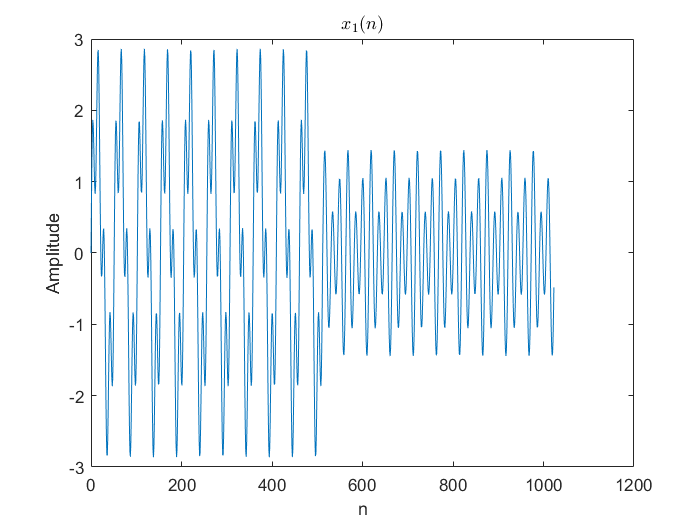


% Visualizing signals

figure;
plot(n, x1_n);
xlabel('n');
ylabel('Amplitude');
title('$x_{1}(n)$', 'Interpreter', 'latex');

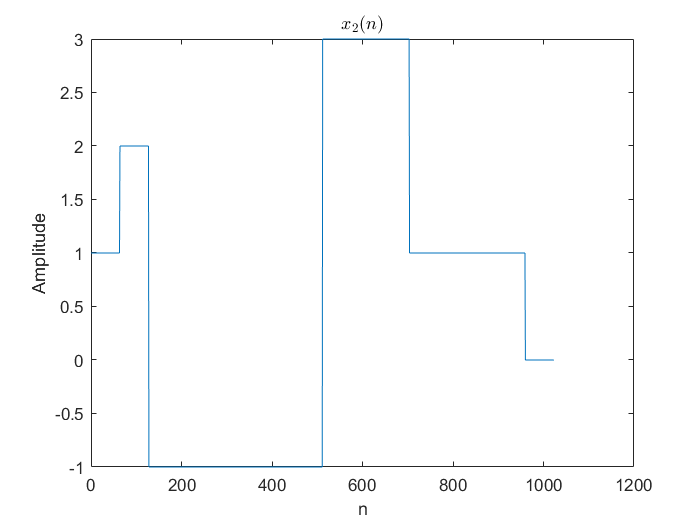


figure;
plot(n, x2_n);
xlabel('n');
ylabel('Amplitude');
title('$x_{2}(n)$', 'Interpreter', 'latex');

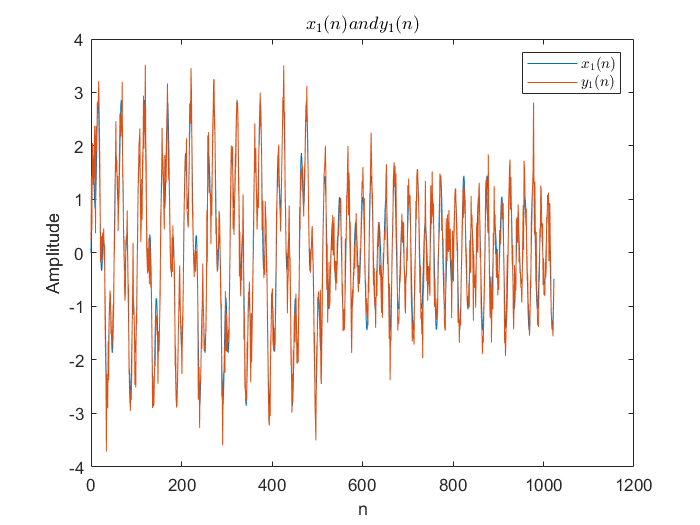

rng(0); % To make sure that the added noise is same to both 
y1_n = awgn(x1_n, 10, 'measured'); % Adding white Gaussian noise to the signal
rng(0);
y2_n = awgn(x2_n, 10, 'measured'); % Adding white Gaussian noise to x2

% Visualizing the noisy signals

figure;
plot(n, x1_n, n, y1_n);
xlabel('n');
ylabel('Amplitude');
title('$x_{1}(n) and y_{1}(n)$', 'Interpreter', 'latex');
legend('$x_{1}(n)$', '$y_{1}(n)$','Interpreter', 'latex');

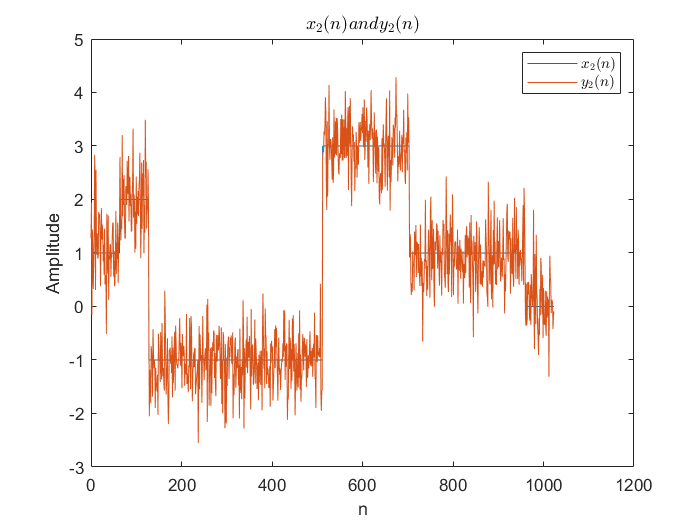


figure;
plot(n, x2_n, n, y2_n);
xlabel('n');
ylabel('Amplitude');
title('$x_{2}(n) and y_{2}(n)$', 'Interpreter', 'latex');
legend('$x_{2}(n)$', '$y_{2}(n)$','Interpreter', 'latex');

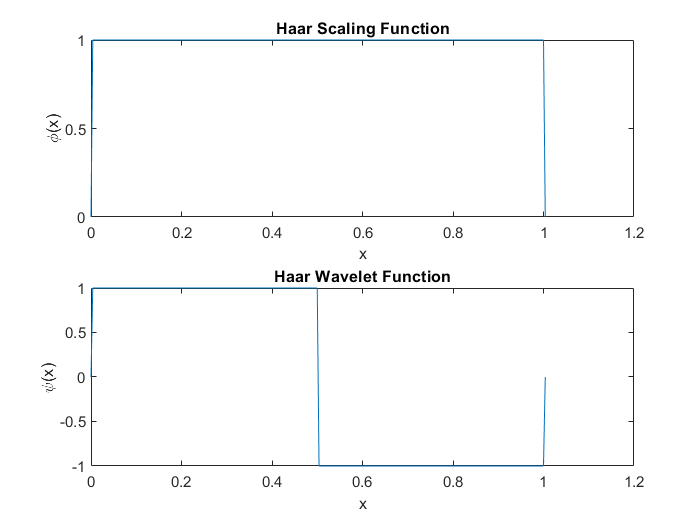

% Observing morphology of haar and db9 wavelet and scaling functions

[phi_haar, psi_haar, xval_haar] = wavefun('haar');  

figure;
subplot(2, 1, 1);
plot(xval_haar, phi_haar);
title('Haar Scaling Function');
xlabel('x');
ylabel('\phi(x)');

subplot(2, 1, 2);
plot(xval_haar, psi_haar);
title('Haar Wavelet Function');
xlabel('x');
ylabel('\psi(x)');

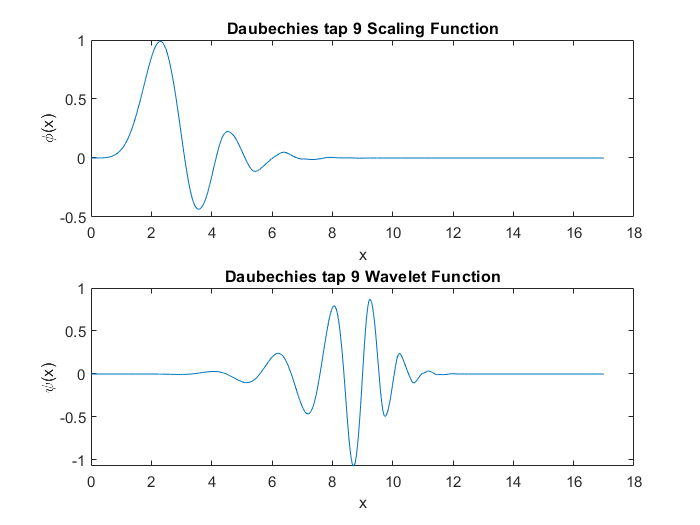


[phi_db9, psi_db9, xval_db9] = wavefun('db9');

figure;
subplot(2, 1, 1);
plot(xval_db9, phi_db9);
title('Daubechies tap 9 Scaling Function');
xlabel('x');
ylabel('\phi(x)');

subplot(2, 1, 2);
plot(xval_db9, psi_db9);
title('Daubechies tap 9 Wavelet Function');
xlabel('x');
ylabel('\psi(x)');

%% Calculating 10 level wavelet decomposition of signals and reconstructing them.

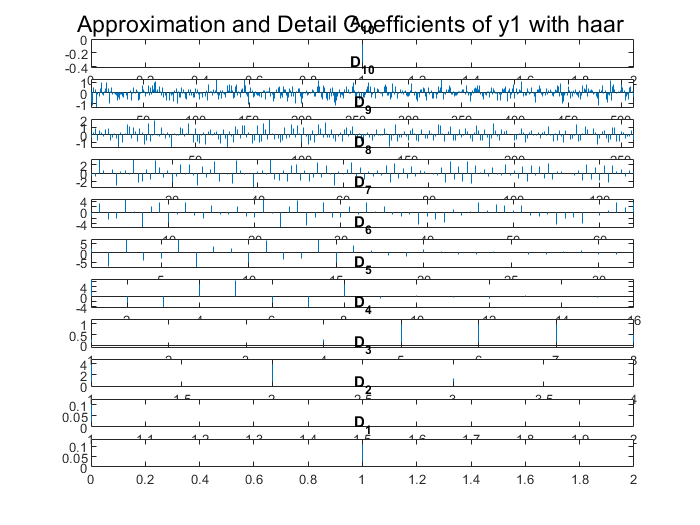

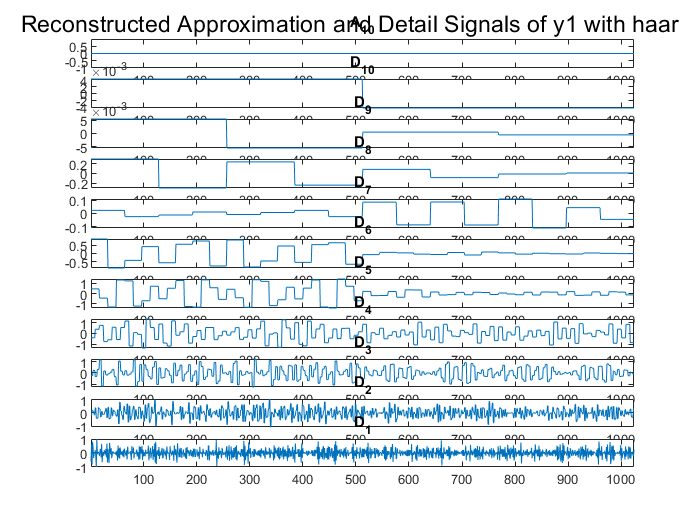

% y1 with haar

[A_10_haar_y1, D_10_haar_y1,D_9_haar_y1,D_8_haar_y1,D_7_haar_y1,...
    D_6_haar_y1,D_5_haar_y1,D_4_haar_y1,D_3_haar_y1,D_2_haar_y1,...
    D_1_haar_y1, reconstructed_signal_haar_y1] = wavelet_analysis(y1_n,'haar','y1 with haar');


det_energy_haar_y1 = det_energy(y1_n, reconstructed_signal_haar_y1); % Calculates energy difference

disp(['Energy difference in y1 with haar: ',num2str(det_energy_haar_y1)]);

Energy difference in y1 with haar: -2.1605e-12


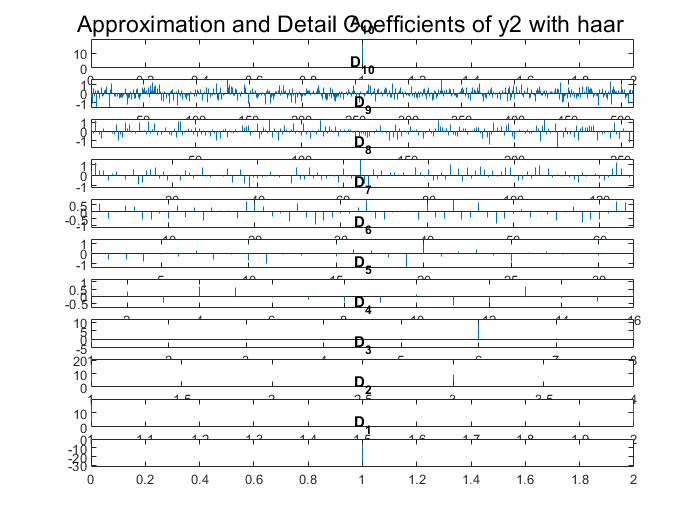

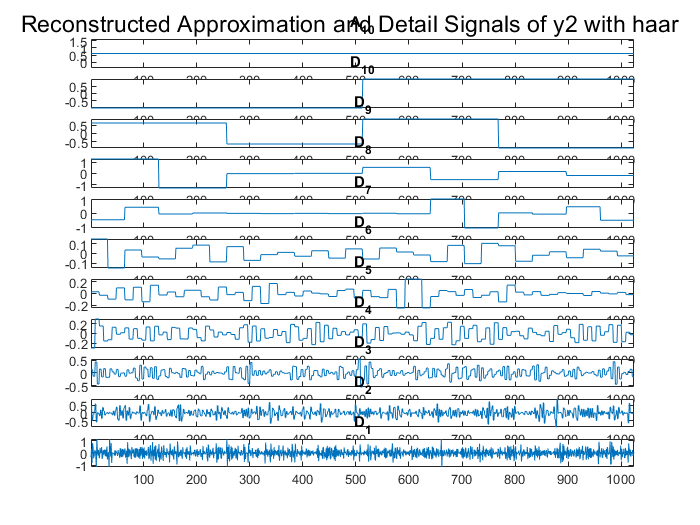

% y2 with haar

[A_10_haar_y2, D_10_haar_y2,D_9_haar_y2,D_8_haar_y2,D_7_haar_y2,...
    D_6_haar_y2,D_5_haar_y2,D_4_haar_y2,D_3_haar_y2,D_2_haar_y2,...
    D_1_haar_y2, reconstructed_signal_haar_y2] = wavelet_analysis(y2_n,'haar', 'y2 with haar');


det_energy_haar_y2 = det_energy(y2_n, reconstructed_signal_haar_y2); % Calculates energy difference

disp(['Energy difference in y2 with haar: ',num2str(det_energy_haar_y2)]);

Energy difference in y2 with haar: -7.2449e-12


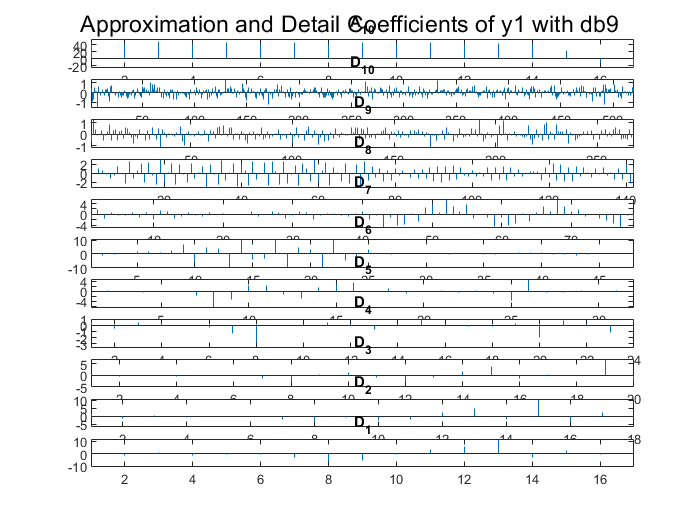

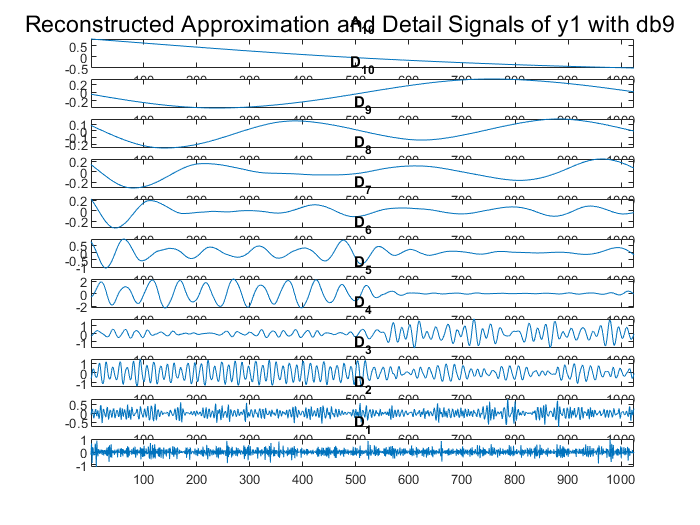

% y1 with db9

[A_10_db9_y1, D_10_db9_y1,D_9_db9_y1,D_8_db9_y1,D_7_db9_y1,...
    D_6_db9_y1,D_5_db9_y1,D_4_db9_y1,D_3_db9_y1,D_2_db9_y1,...
    D_1_db9_y1, reconstructed_signal_db9_y1] = wavelet_analysis(y1_n,'db9', 'y1 with db9');


det_energy_db9_y1 = det_energy(y1_n, reconstructed_signal_db9_y1); % Calculates energy difference

disp(['Energy difference in y1 with db9: ',num2str(det_energy_db9_y1)]);

Energy difference in y1 with db9: 3.1147e-07


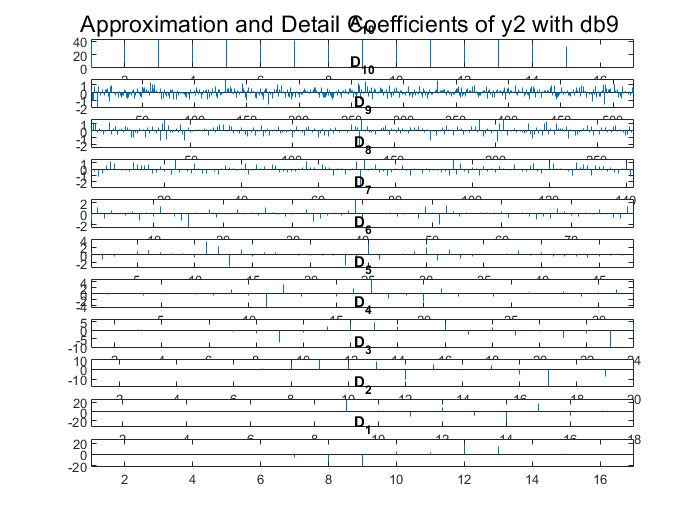

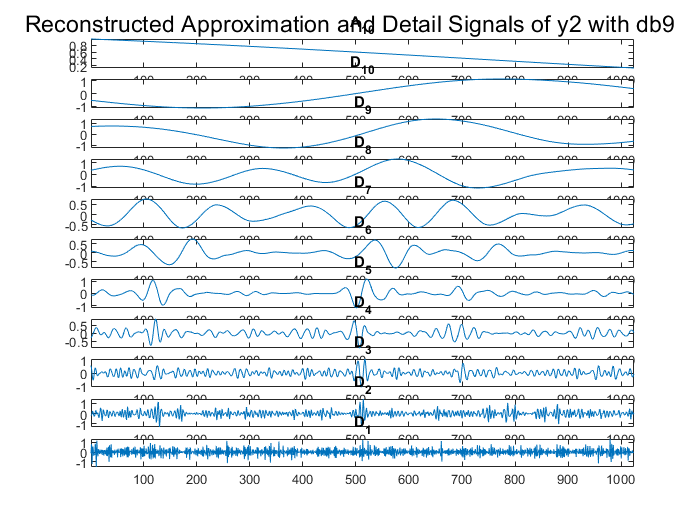

% y2 with db9

[A_10_db9_y2, D_10_db9_y2,D_9_db9_y2,D_8_db9_y2,D_7_db9_y2,...
    D_6_db9_y2,D_5_db9_y2,D_4_db9_y2,D_3_db9_y2,D_2_db9_y2,...
    D_1_db9_y2, reconstructed_signal_db9_y2] = wavelet_analysis(y2_n,'db9', 'y2 with db9');


det_energy_db9_y2 = det_energy(y2_n, reconstructed_signal_db9_y2); % Calculates energy difference

disp(['Energy difference in y2 with db9: ',num2str(det_energy_db9_y2)]);

Energy difference in y2 with db9: 5.0957e-07


## 2.3. Signal Denoising with DWT

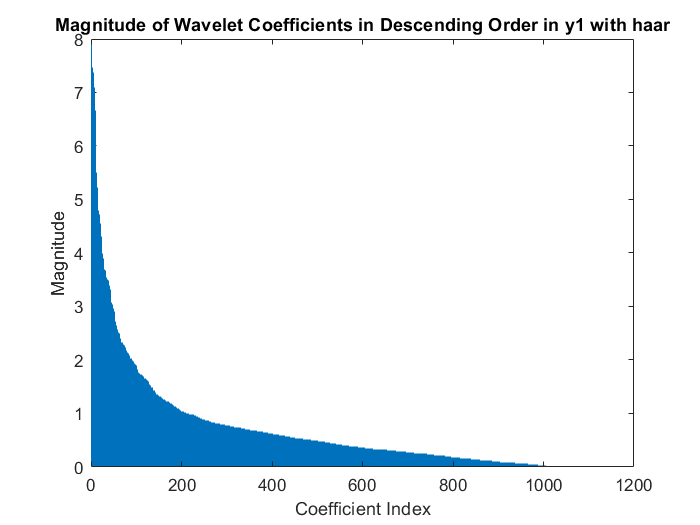

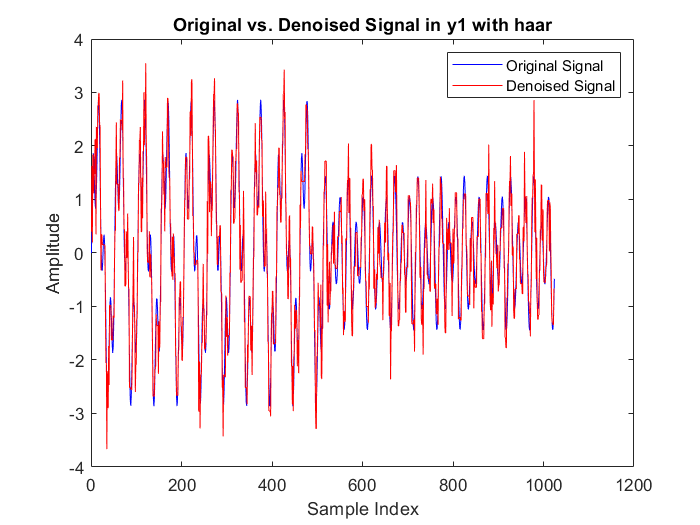

% Denoises signal using thresholded wavelet coefficients. 
% RMSE is used to measure the denoising. 

% y1 with haar

haar_y1_thresh = 0.5; 
[denoised_haar_y1, RMSE_haar_y1] = wavelet_denoise(x1_n, y1_n, haar_y1_thresh ,'haar', 'y1 with haar');

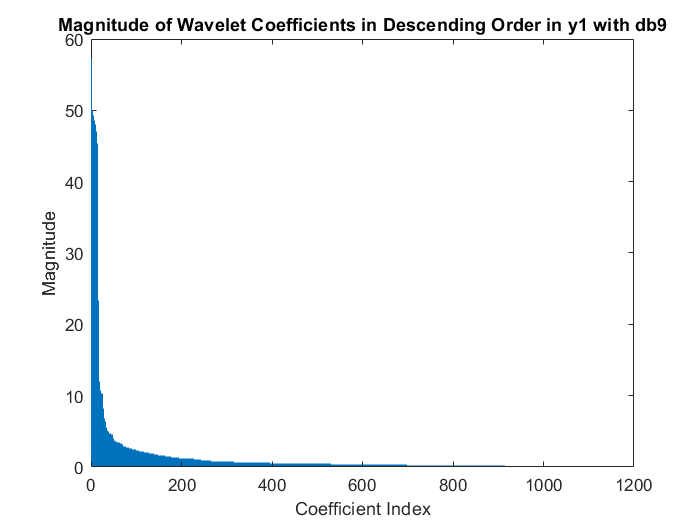

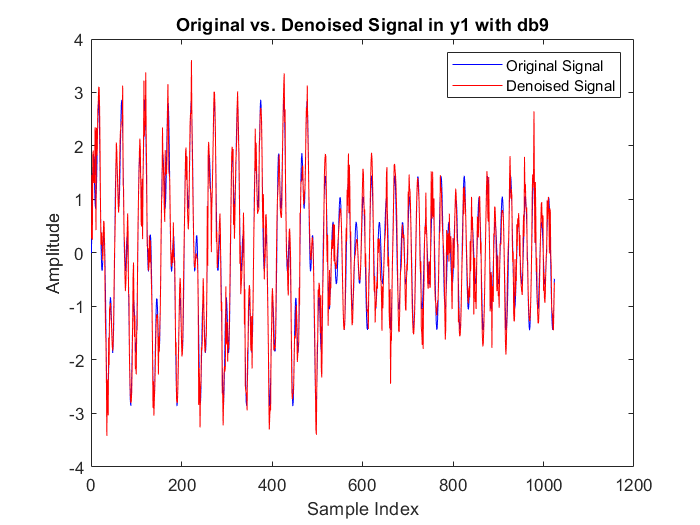


% y1 with db9

db9_y1_thresh = 0.5;
[denoised_db9_y1, RMSE_db9_y1]  = wavelet_denoise(x1_n, y1_n, db9_y1_thresh, 'db9', 'y1 with db9');

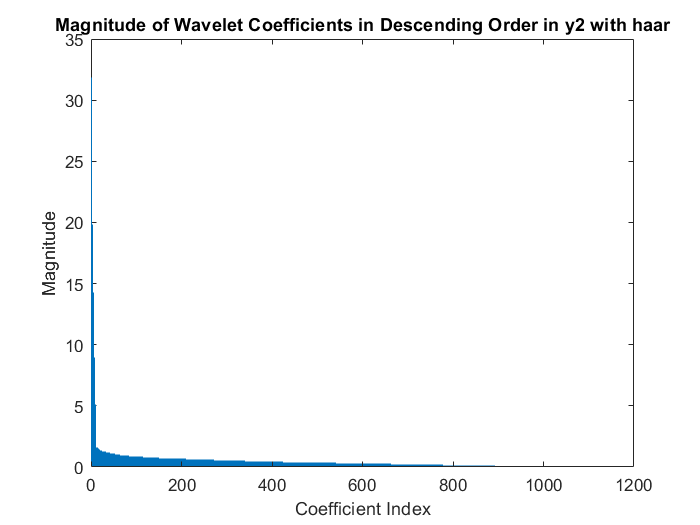

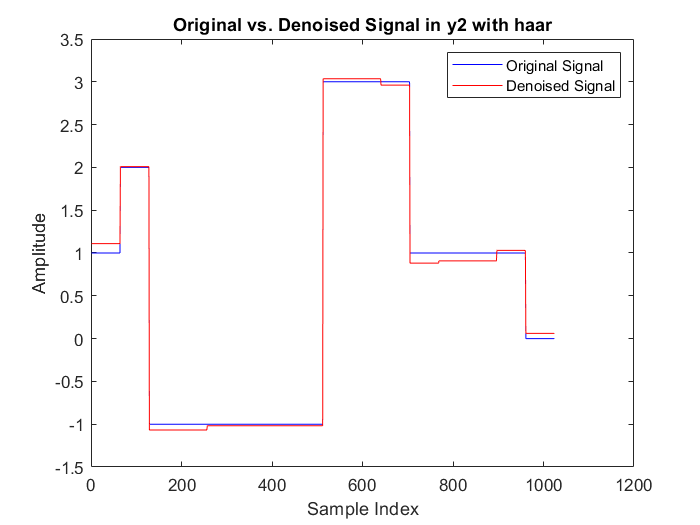


% y2 with haar

haar_y2_thresh = 2;
[denoised_haar_y2, RMSE_haar_y2] = wavelet_denoise(x2_n, y2_n, haar_y2_thresh, 'haar', 'y2 with haar');

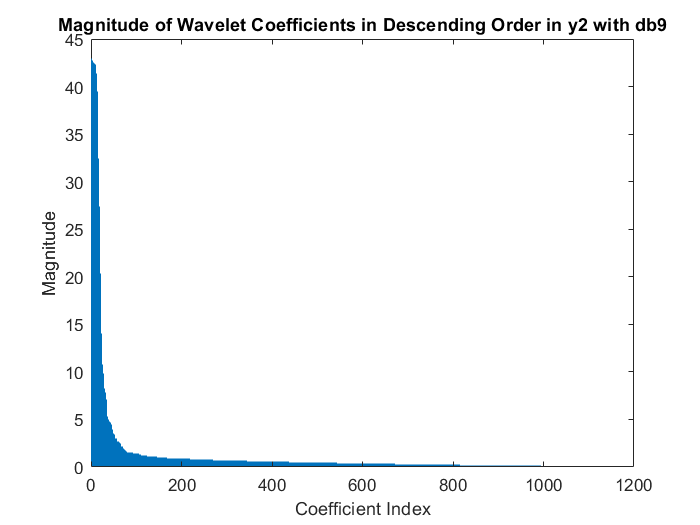

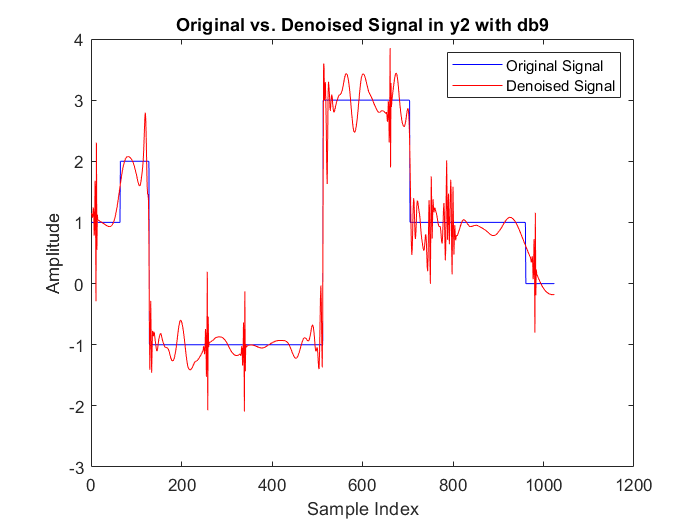


% y2 with db9

db9_y2_thresh = 1.5;
[denoised_db9_y2, RMSE_db9_y2] = wavelet_denoise(x2_n, y2_n, db9_y2_thresh, 'db9', 'y2 with db9');


disp(['RMSE, y1 with haar: ', num2str(RMSE_haar_y1)]);

RMSE, y1 with haar: 0.39573


disp(['RMSE, y1 with db9: ', num2str(RMSE_db9_y1)]);

RMSE, y1 with db9: 0.34503


disp(['RMSE, y2 with haar: ', num2str(RMSE_haar_y2)]);

RMSE, y2 with haar: 0.062462


disp(['RMSE, y2 with db9: ', num2str(RMSE_db9_y2)]);

RMSE, y2 with db9: 0.27379
